# Tutorial03 Random Walks

#### Notes

Overview

In this lab, we will:

- generate a # of 2D random walks

- Plot a few such trajectories

- Take a look at the distribution of a large # of random walkers.

Goal

For us to get an intuitive feeling of what a random walk actually looks like.

Definition

**Random walk**. A mathematical formulation. The "movements of an object or changes in a variable that follow no discernible pattern or trend."

Another source: "n. Statistics. A sequence of changes, either in the value of a **random** variable or in a process (as in the price of a share of stock), in which the direction and size of each change is randomly determined, subject to some specified rules."

Without further ado, let's go!

1 Useful Matlab Commands

a1 = [1, 2, 3]

a1 =      1     2     3


b1 = [1; 2; 3]

b1 =      1
     2
     3


c1 = [1, 2, 3]'

c1 =      1
     2
     3


d1 = [1, 2, 3; 4, 5, 6]

d1 =      1     2     3
     4     5     6


Recap.

- The [] lets us specify a list or array.

- ' is for transpose.

x = 1+2

x = 3

disp('message')

message


disp(num2str(x))

3


disp(['The value of x= ', num2str(x, 10), '.'])

The value of x= 3.


**disp** is like printf in C or print in Python.

The [] bundles the three items into a single string of characters.

We can use the same trick to title a graph.

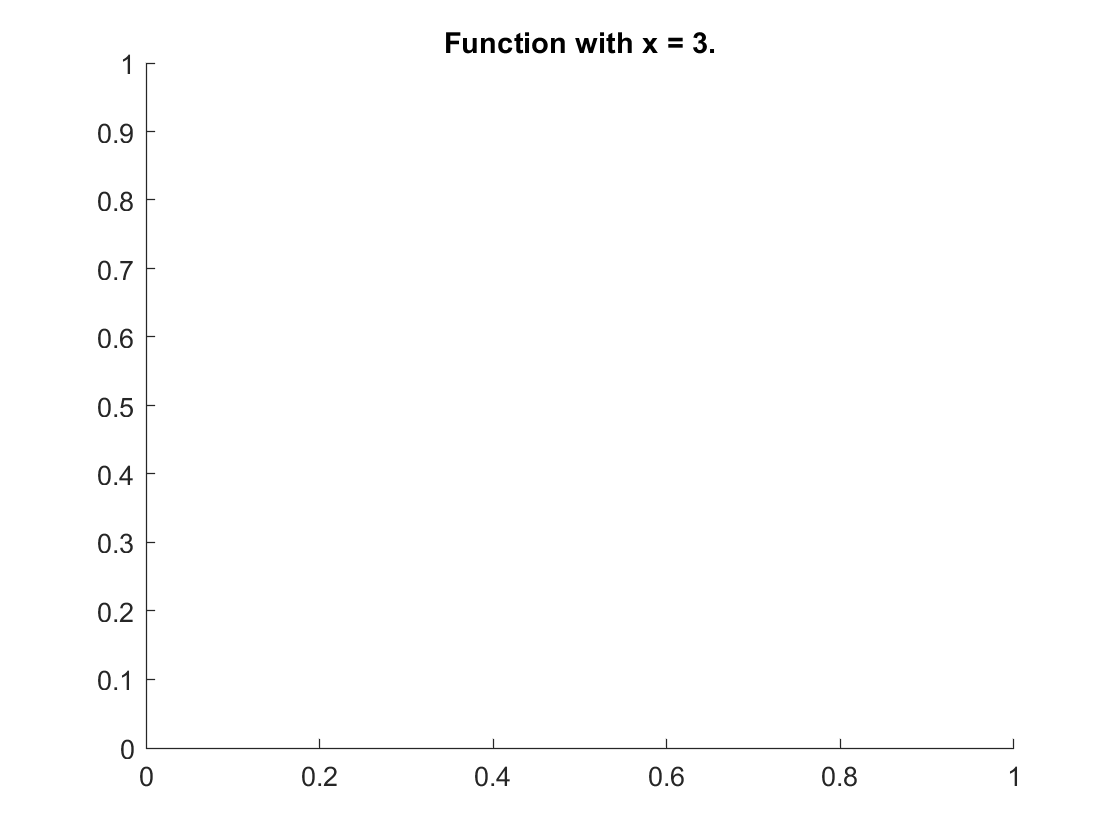

title(['Function with x = ', num2str(x, 10), '.'])

Note: num2str has an optional second arg, the # of sig digs to show.

Some functions

**rand**: generate a uniformly distributed rand # btw 0 and 1. rand(1, n) generates n such #s. rand(3,7) generates a 3 x 7 array.

rand(1,3);
rand(3,8);

**semilogy**: plot with log base 10 y-axis.

**for** **loop**: 

-----------

for i = 1:1000

    [list of commands]

end

-----------

Recap: **end** closes the scope of the **for**.

**i** is the **control variable**.

We can also make nested for loops.

CAUTION: we can use the value of i inside the loop, but BETTER NOT TO change the value of i.

-----------

for i = 1:1000

for j = 1:10

    [list of commands] % this will be executed 10,000 times

end end

-----------

a = 3; b = 2;
a > b;
a < b;
% a = b
a == b %#ok<EQEFF> 

ans = logical
   0


a == 3 %#ok<EQEFF> 

ans = logical
   1



if a > b
    display([num2str(a), ' is bigger than ', num2str(b)])
elseif a == b
    display(['a and b are equal. They are both ', num2str(a)])
else
    display([num2str(b), 'is bigger than ', num2str(a)])
end

3 is bigger than 2


-----------

The **break** command. Prematurely terminates a loop and goes immediatemly to the command after the loop. (c.f. **disp** command in this case).

% a = 3  % this line will make the loop run 1000 times.
n = 1000

n = 1000

for i = 1:n
  disp(i)
  if a > b
      break
  end % this closes the "if"
end

     1



disp('done')

done


-----------

**Histogram**

hist(v,n)

v = [1 2 3 4 5 6 7 8 9]

v =      1     2     3     4     5     6     7     8     9


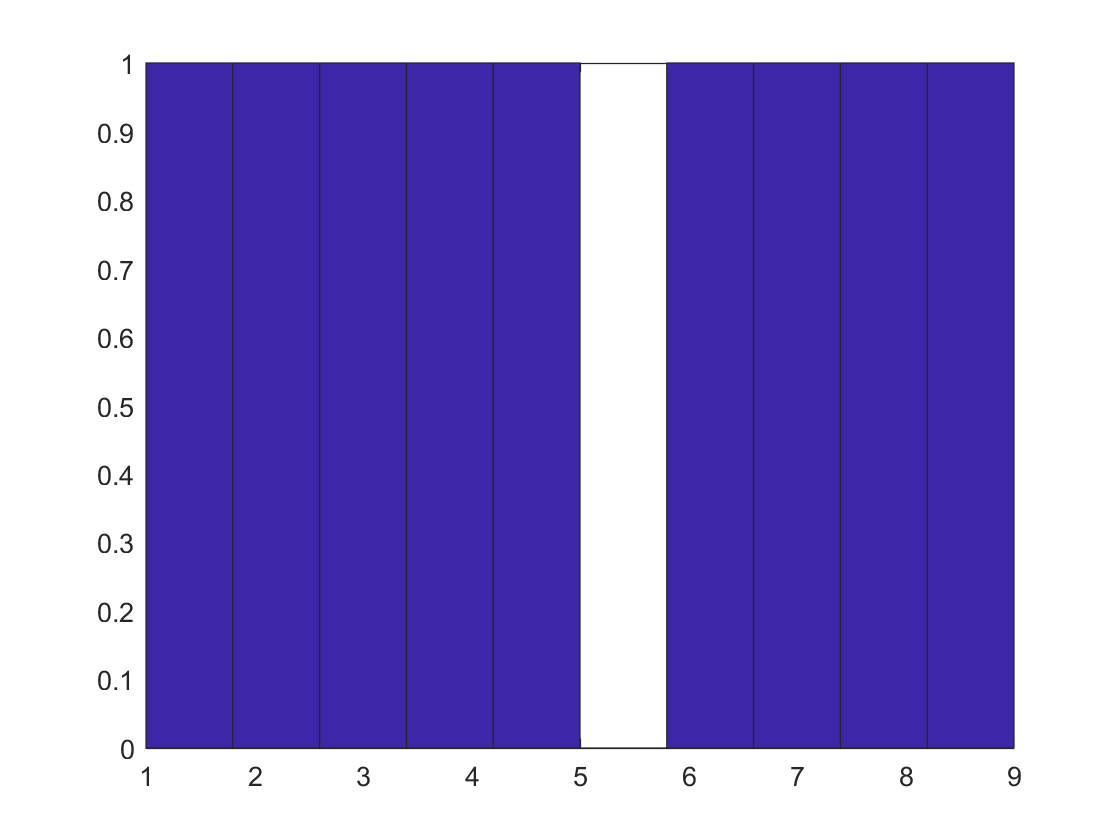

hist(v, 10)

Produces a histogram of the values contained in the vector **v** with 3 bins.

If we just do **hist(v)**, it would try to guess the # of bins <- not always successful.

For more information,

% help hist

-----------

set(gca, 'FontSize', xx)

After making a plot, the above command will change the font size on the axes to xx.

set(gca, 'FontSize', 16)

The var **gca** is MATLAB's way of denoting the most recently drawn graph.

2. Random Walks

2.1 Goals

- To generate some rand walk trajectories, each of which starts at the origin and proceeds in rand diagona steps according to: xn+1 = xn ±1, yn+1 = yn ±1

- Plot the full trajecs of 3 such walks in 3 separate figures.

- Plot all the endpoints of the trajecs in a single figure to see their distribution.

- Calculate the avg pos of the walkers and their avg distance from the original, and cmpr each to an expected result.

First, will examine some simpler systems.

2.2 Heads or Tails? - Simulating Coin Flips

1 > 2;  % will give 0

** We can simulate a coin flip by using the **rand** to generate a uniformly distributed var, then convert it to a binary digit by comparing it to 1/2.

% help rand
rlist = rand(1, 100)

rlist =     0.6610    0.3811    0.1362    0.0966    0.3052    0.8239    0.6273    0.2059    0.9802    0.4378    0.8352    0.5392    0.0251    0.0068    0.7861    0.4474    0.2887    0.8632    0.6562    0.2847    0.6446    0.2636    0.1748    0.3686    0.5375    0.9264    0.7491    0.1477    0.0029    0.1270    0.9169    0.6721    0.1138    0.9602    0.1194    0.4924    0.3613    0.4700    0.0588    0.3300    0.2645    0.2459    0.9477    0.0324    0.9062    0.3685    0.6625    0.9536    0.0941    0.6853


rlist = (rlist>0.5) %% IMPT line

rlist = 1×100 logical array
   1   0   0   0   0   1   1   0   1   0   1   1   0   0   1   0   0   1   1   0   1   0   0   0   1   1   1   0   0   0   1   1   0   1   0   0   0   0   0   0   0   0   1   0   1   0   1   1   0   1


sum(rlist)  % count the heads, assuming head = 1x

ans = 43

**2.3 Wandering on a Plane - Generating Trajectories**

Now: Want to create a rand walk of 500 steps.

=> Our trajectory will be a list of 500 x values and 500 y values.

Note: It's a good practice to let MATLAB know the length of the lists, bc it saves computation time.

walklength = 500;
x = zeros(1, walklength); y = zeros(1, walklength)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


eqn1 shows that we can consider x and y separately.

% Creating two lists of 500 random binary digits
rlistx = rand(1, walklength)

rlistx =     0.2873    0.7414    0.0670    0.7572    0.2407    0.2309    0.0120    0.1325    0.2094    0.2142    0.9058    0.2778    0.0971    0.7828    0.6675    0.6127    0.3438    0.6903    0.2336    0.3080    0.3573    0.2167    0.6773    0.7360    0.0100    0.3559    0.2400    0.9276    0.7630    0.3794    0.6860    0.6989    0.5904    0.9621    0.7813    0.5384    0.0941    0.8860    0.2575    0.4635    0.3308    0.7568    0.8028    0.8031    0.8766    0.0875    0.6679    0.5024    0.3356    0.5886


rlisty = rand(1, walklength)

rlisty =     0.3025    0.1418    0.8443    0.2882    0.9088    0.1132    0.6139    0.2839    0.5081    0.5389    0.0522    0.4371    0.2187    0.9183    0.6915    0.1159    0.3596    0.3061    0.3022    0.5614    0.7961    0.4699    0.7912    0.4188    0.7395    0.3575    0.9498    0.7501    0.0196    0.7552    0.9118    0.3478    0.0713    0.8551    0.0944    0.5496    0.9155    0.5220    0.0520    0.4409    0.6912    0.2614    0.8959    0.4597    0.2320    0.1959    0.8497    0.7416    0.6622    0.1071


stepx = (rlistx>0.5)

stepx = 1×500 logical array
   0   1   0   1   0   0   0   0   0   0   1   0   0   1   1   1   0   1   0   0   0   0   1   1   0   0   0   1   1   0   1   1   1   1   1   1   0   1   0   0   0   1   1   1   1   0   1   1   0   1


stepy = (rlisty>0.5)

stepy = 1×500 logical array
   0   0   1   0   1   0   1   0   1   1   0   0   0   1   1   0   0   0   0   1   1   0   1   0   1   0   1   1   0   1   1   0   0   1   0   1   1   1   0   0   1   0   1   0   0   0   1   1   1   0


sum(stepx);
sum(stepx);

Now, convert the lists of steps into actual successive positions of the random walker.

% help cumsum
stepx = cumsum(-1+2*stepx)

stepx =     -1     0    -1     0    -1    -2    -3    -4    -5    -6    -5    -6    -7    -6    -5    -4    -5    -4    -5    -6    -7    -8    -7    -6    -7    -8    -9    -8    -7    -8    -7    -6    -5    -4    -3    -2    -3    -2    -3    -4    -5    -4    -3    -2    -1    -2    -1     0    -1     0


stepy = cumsum(-1+2*stepy)

stepy =     -1    -2    -1    -2    -1    -2    -1    -2    -1     0    -1    -2    -3    -2    -1    -2    -3    -4    -5    -4    -3    -4    -3    -4    -3    -4    -3    -2    -3    -2    -1    -2    -3    -2    -3    -2    -1     0    -1    -2    -1    -2    -1    -2    -3    -4    -3    -2    -1    -2


2.4 Plotting Trajectories

Assignment

>> In tut03_assignment_2.4.mlx

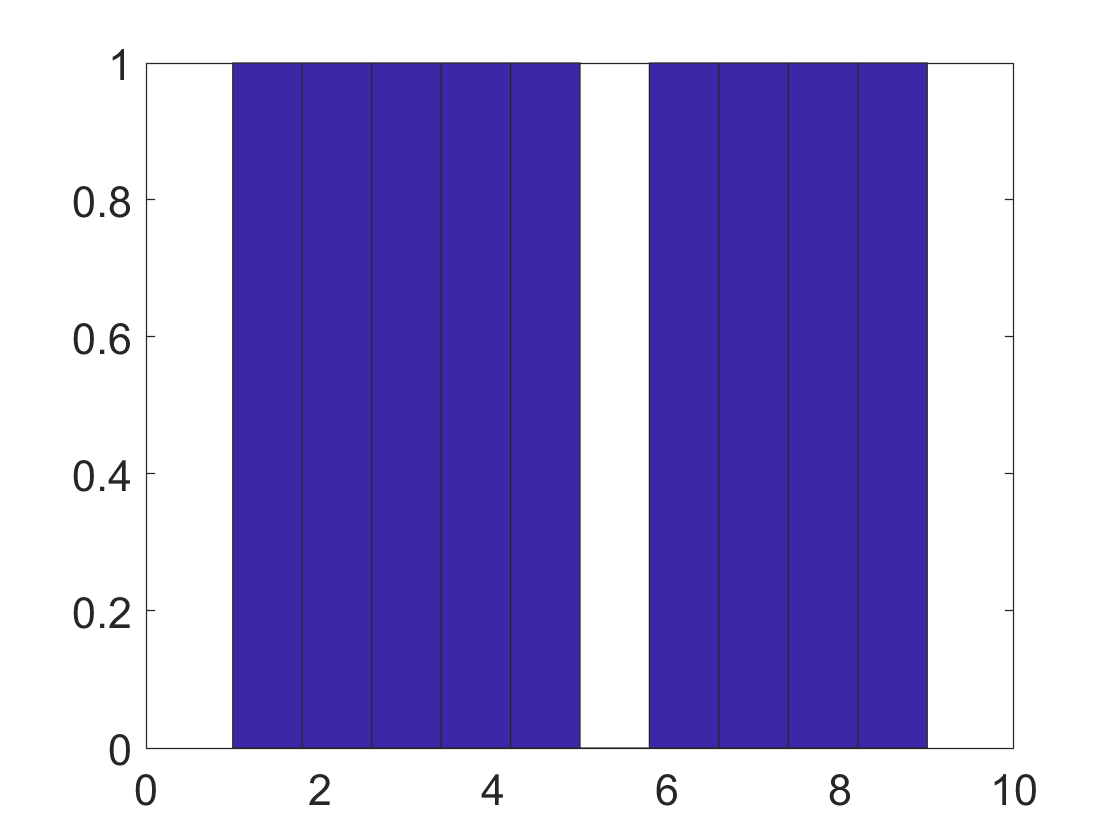

edit tut02_assignment_2.4.mlx